Initialize Parameters

n = 1000; % number of locations to evaluate 
L = 1250; % length of bridge
x = linspace(0, L, n); % create coordinate system
SFD_PL = zeros(1, n); % Initialize SFD(x) for point loads

Point Loading Analysis (SFD, BMD)

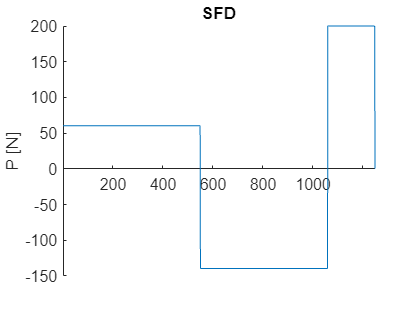

P = 200;
[SFD_PL, ~] = ApplyPL(550, P, x, SFD_PL); % Construct SFD, BMD 
[SFD_PL, BMD_PL] = ApplyPL(L, P, x, SFD_PL); % Construct SFD, BMD
% Plot SFD
figure;
hold on;
title("SFD");
ylabel("P [N]");
plot(x, SFD_PL);
ax = gca;
ax.XAxisLocation = 'origin';
xlim([0, x(n)]);
hold off;

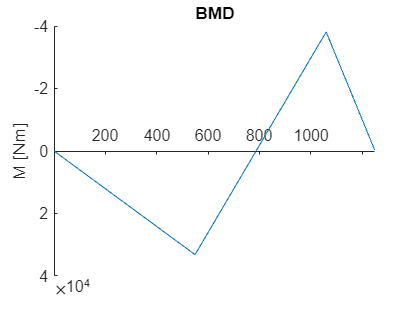


% Plot BMD
figure;
hold on;
title("BMD");
ylabel("M [Nm]");
plot(x, BMD_PL);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YDir = 'reverse';
xlim([0, x(n)]);
hold off;

Define cross-sections

xc = [0 786 L]; % Location, x, of cross-section change FIRST VALUE MUST BE 0 AND LAST VALUE MUST BE L
bft = [100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27]; % Top Flange Thickness
hw = [75 75 75]; % Web Height
tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate
bfb = [80 80 80]; % Bottom Flange Width
tfb = [1.27 1.27 1.27]; % Bottom Flange Thickness
apositions = [-15 15 130 260 390 535 565 700 800 900 1045 1075 1235 1265]; % Diaphragm Positions
aspacings = apositions(2:end) - apositions(1:end-1); % Diaphragm Spacings
%amax = max(aspacings); % Largest Diaphragm Spacing
amax = 520; % Largest DIaphragm Spacing override
tt = [10 10 10]; % Thickness of glue tab
% NOTE: Glue tabs are not considered for Section properties calculations
% Only used for Glue shear calculations
[ybar, I, Qcent, Qglue] = SectionProperties(xc, tft, bft, hw, tw, tfb, bfb, x);

Define Material Properties

SigT = 30;
SigC = 6;
E = 4000;
TauU = 4;
TauG = 2;
mu = 0.2;

Calculate Failure Moments and Shear Forces

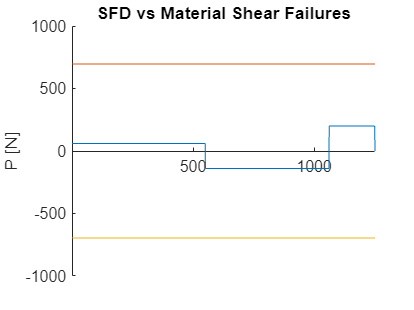

V_Mat = Vfail(I, Qcent, tw, x, xc, TauU); % Assume y_bar lies on the web, so b = tw * 2
V_Glue = Vfail(I, Qglue, tt, x, xc, TauG);
V_Buck = VfailBuck(x, xc, tw, hw, E, mu, amax, I, Qcent);
[M_MatT, M_MatC] = MfailMatTC(I, tft, tfb, hw, xc, x, ybar, SigT, SigC, BMD_PL); % only for point load
[M_BuckMid, M_BuckSide, M_BuckWeb] = MfailBuck(I, tft, tfb, tw, hw, bft, bfb, ybar, xc, x, E, mu, BMD_PL );
% plot material shear failure
figure;
hold on;
title("SFD vs Material Shear Failures");
ylabel("P [N]");
plot(x, SFD_PL);
plot(x, V_Mat);
plot(x, -V_Mat);
ax = gca;
ax.XAxisLocation = 'origin';
xlim([0, x(n)]);
hold off;

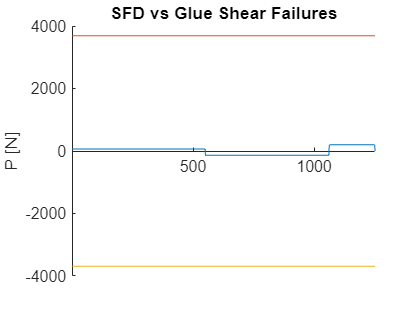


% plot glue shear failure
figure;
hold on;
title("SFD vs Glue Shear Failures");
ylabel("P [N]");
plot(x, SFD_PL);
plot(x, V_Glue);
plot(x, -V_Glue);
ax = gca;
ax.XAxisLocation = 'origin';
xlim([0, x(n)]);
hold off;

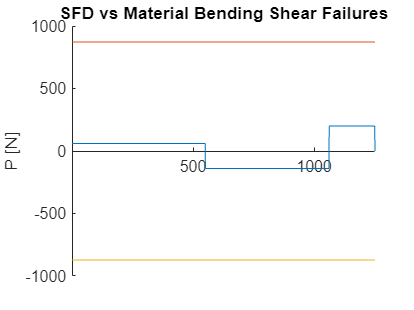


% plot material bending shear failure
figure;
hold on;
title("SFD vs Material Bending Shear Failures");
ylabel("P [N]");
plot(x, SFD_PL);
plot(x, V_Buck);
plot(x, -V_Buck);
ax = gca;
ax.XAxisLocation = 'origin';
xlim([0, x(n)]);
hold off;

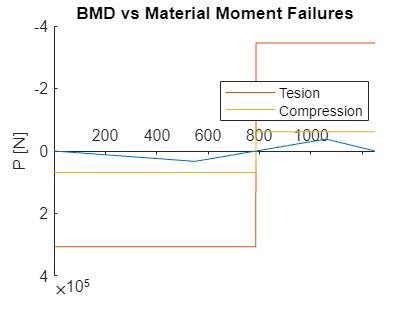


% plot material moment tension and compression failures
figure;
hold on;
title("BMD vs Material Moment Failures");
ylabel("P [N]");
plot(x, BMD_PL);
plot(x, M_MatT);
plot(x, M_MatC);
legend("","Tesion", "Compression", Location="best")
ax = gca;
ax.XAxisLocation = 'origin';
ax.YDir = 'reverse';
xlim([0, x(n)]);
hold off;

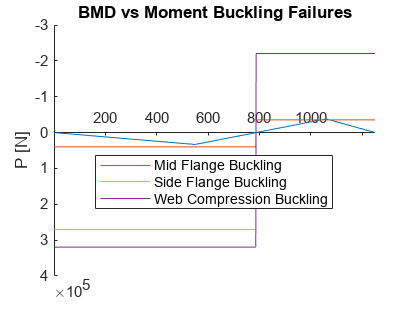


% plot material moment Buckling failures
figure;
hold on;
title("BMD vs Moment Buckling Failures");
ylabel("P [N]");
plot(x, BMD_PL);
plot(x, M_BuckMid);
plot(x, M_BuckSide);
plot(x, M_BuckWeb);
legend("","Mid Flange Buckling", "Side Flange Buckling", "Web Compression Buckling", Location="best")
ax = gca;
ax.XAxisLocation = 'origin';
ax.YDir = 'reverse';
xlim([0, x(n)]);
hold off;

Calculate Failure Load

% Gives the failure load and says where the bridge had failed
[Pf] = FailLoad(P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_BuckMid, M_BuckSide, M_BuckWeb)

M_BuckMid


Pf = 186

Train Loading Analysis  

% Construct SFD, BMD for train loading
P_train = 400 / 6;
SFD_train = zeros(1, n); % Initialize SFD(x) for train
bridge_failed = false;
FOS = 100;
i = 0;
% Checks for every position of the trains on the bridge
while 856 + i < L
 [SFD_train, ~] = ApplyPL(52 - 52 + i, P_train, x, SFD_train);
 [SFD_train, ~] = ApplyPL(228 - 52 + i, P_train, x, SFD_train);
 [SFD_train, ~] = ApplyPL(392 - 52 + i, P_train, x, SFD_train);
 [SFD_train, ~] = ApplyPL(568 - 52 + i, P_train, x, SFD_train);
 [SFD_train, ~] = ApplyPL(732 - 52 + i, P_train, x, SFD_train);
 [SFD_train, BMD_train] = ApplyPL(908 - 52 + i, P_train, x, SFD_train);
 % check if bridge fails under train load
 [Pf_train] = FailLoad(P_train, SFD_train, BMD_train, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_BuckMid, M_BuckSide, M_BuckWeb);
 % checks as assigns the lowest FOS during the train loading
 if Pf_train/P_train < FOS
 FOS = Pf_train/P_train;
 end
 if Pf_train < P_train
 disp("Bridge will FAIL under train load.")
 bridge_failed = true;
 break
 end
 i = i + 1;
 SFD_train = SFD_train .* 0;
end

M_BuckMid


Bridge will FAIL under train load.


if bridge_failed == false
 disp("Bridge will NOT FAIL under train load.")
end
disp("FOS: "+FOS)

FOS: 0.735


Curvature, Slope, & Deflections 

[deflection] = Deflections(x, BMD_PL, I, E, L)

deflection =        NaN       NaN    0.0102    0.0153    0.0205    0.0256    0.0307    0.0358    0.0409    0.0460    0.0511    0.0563    0.0614    0.0665    0.0716    0.0767    0.0818    0.0869    0.0920    0.0971    0.1022    0.1073    0.1124    0.1175    0.1226    0.1277    0.1328    0.1379    0.1430    0.1481    0.1531    0.1582    0.1633    0.1684    0.1735    0.1785    0.1836    0.1887    0.1937    0.1988    0.2039    0.2089    0.2140    0.2190    0.2241    0.2291    0.2342    0.2392    0.2442    0.2493


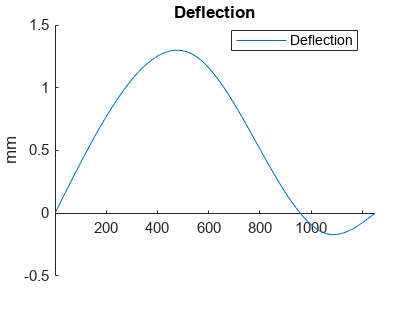

figure;
hold on;
title("Deflection");
ylabel("mm");
plot(x(1:size(deflection,2)), deflection);
legend("Deflection", Location="best")
ax = gca;
ax.XAxisLocation = 'origin';
xlim([0, x(n)]);
hold off;


% Gets deflection at midspan (between supports)
deflection_mid = deflection(1,(1060/2)/(L/n))

deflection_mid = 1.2747

Functions

function [SFD, BMD] = ApplyPL(xP, P, x, SFD)
 % Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports 
 % Input: location and magnitude of point load. The previous SFD can be entered as input to construct SFD of multiple point loads 
 % Output: SFD, BMD both 1-D arrays of length n
 location_1 = 0; % Location of support A
 location_2 = location_1 + 1060; % Location of support B
 reaction_1 = (location_2 - xP) * P / (location_2 - location_1); % Force excerted by support A
 reaction_2 = P - reaction_1; % Force excerted by support B
 sz = size(x, 2);
 for i = 1:sz
 % Find value of SFD at location x
 if x(i) >= location_1
 SFD(i) = SFD(i) + reaction_1;
 end
 if x(i) >= xP
 SFD(i) = SFD(i) - P;
 end
 if x(i) >= location_2
 SFD(i) = SFD(i) + reaction_2;
 end
 end
 BMD = zeros(1, sz);
 for i = 2:sz
 % Find value of BMD at location x
 BMD(i) = BMD(i - 1) + SFD(i) * (x(i) - x(i - 1));
 end
end
function [ybar, I, Qcent, Qglue] = SectionProperties(xc, tft, bft, hw, tw, tfb, bfb, x)
 % Calculates important sectional properties: ybar, I, Qcent, Qglue
 % Input: Geometric Inputs
 % Output: Sectional Properties at every value of x. Each property is a 1-D array of length n
 % Ignores diaphragms
 sz = size(x, 2);
 section_number = size(xc, 2) - 1; 
 % Calculate ybar
 ybar = zeros(1, sz);
 area_total = zeros(1, sz);
 y_0_t = zeros(1, sz);
 y_0_w = zeros(1, sz);
 y_0_b = zeros(1, sz);
 A_t = zeros(1, sz);
 A_w = zeros(1, sz);
 A_b = zeros(1, sz);
 for i = 1:sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 A_t(i) = tft(j) * bft(j);
 A_w(i) = hw(j) * tw(j);
 A_b(i) = tfb(j) * bfb(j);
 y_0_b(i) = tfb(j) / 2;
 y_0_w(i) = tfb(j) + hw(j) / 2;
 y_0_t(i) = tfb(j) + hw(j) + tft(j) / 2;
 area_total(i) = A_t(i) + 2 * A_w(i) + A_b(i);
 ybar(i) = (A_b(i) * y_0_b(i) + 2 * A_w(i) * y_0_w(i) + A_t(i) * y_0_t(i)) / area_total(i);
 break
 end
 end
 end
 % calculate I
 I = zeros(1, sz);
 I_0_t = zeros(1, sz);
 I_0_w = zeros(1, sz);
 I_0_b = zeros(1, sz);
 d_0_t = zeros(1, sz);
 d_0_w = zeros(1, sz);
 d_0_b = zeros(1, sz);
 for i = 1:sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 d_0_t(i) = abs(y_0_t(i) - ybar(i));
 d_0_w(i) = abs(y_0_w(i) - ybar(i));
 d_0_b(i) = abs(y_0_b(i) - ybar(i));
 I_0_t(i) = bft(j) * tft(j) ^ 3 / 12;
 I_0_w(i) = tw(j) * hw(j) ^ 3 / 12;
 I_0_b(i) = bfb(j) * tfb(j) ^ 3 / 12;
 I(i) = I_0_t(i) + d_0_t(i) ^ 2 * A_t(i) + 2 * (I_0_w(i) + d_0_w(i) ^ 2 * A_w(i)) + I_0_b(i) + d_0_b(i) ^ 2 * A_b(i);
 break
 end
 end
 end
 % calculate Qcent
 Qcent = zeros(1, sz);
 for i = 1:sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 %Qcent(i) = d_0_t(i) * A_t(i) + 2 * (tfb(j) + hw(j) - ybar(i)) / 2 * A_w(i);
 Qcent(i) = d_0_b(i) * A_b(i) + 2 * (ybar(i)-tfb(j)) / 2 * (tw(j)*(ybar(i)-tfb(j)));
 break
 end
 end
 end
 % calculate Qglue
 Qglue = zeros(1, sz);
 for i = 1:sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 Qglue(i) = d_0_t(i) * A_t(i);
 break
 end
 end
 end
end
function [V_fail] = Vfail(I, Qcent, tw, x, xc, TauU)
 % Calculates shear forces at every value of x that would cause a matboard shear failure
 % Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property)
 % Output: V_fail a 1-D array of length n
 sz = size(x, 2);
 section_number = size(xc, 2) - 1; 
 b = zeros(1, sz);
 for i = 1:sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 b(i) = tw(j) * 2;
 break
 end
 end
 end
 V_fail = TauU .* I .* b ./ Qcent;
end
function [V_Buck] = VfailBuck(x, xc, tw, hw, E, mu, amax, I, Qcent)
 % Calculates shear forces at every value of x that would cause a shear buckling failure
 % Input: Sectional Properties (list of 1-D arrays), E, mu (material property) 
 % Output: V_Buck, a 1-D array of length n
 sz = size(x, 2);
 section_number = size(xc, 2) - 1; 
 V_Buck = nan(1, sz);
 for i = 1:sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 V_Buck(i) = 5 * pi ^ 2 * E / 12 / (1 - mu ^ 2) * ((tw(j) / hw(j)) ^ 2 + (tw(j) / amax) .^ 2) * I(i) * (tw(j)*2) / Qcent(i);
 break
 end
 end
 end
end
function [ M_MatT, M_MatC ] = MfailMatTC(I, tft, tfb, hw, xc, x, ybar, SigT, SigC, BMD)
 % Calculates bending moments at every value of x that would cause a matboard tension failure
 % Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array)
 % Output: M_MatT and M_MatC, 1-D arrays of length n
 section_number = size(xc, 2) - 1; 
 sz = size(x, 2);
 M_MatT = nan(1, sz);
 M_MatC = nan(1, sz);
 for i = 1 : sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 ytop(i) = tfb(j) + hw(j) + tft(j) - ybar(i);
 ybot(i) = ybar(i);
 if BMD(i) > 0 % If the moment is positive, the tension is at the bottom compression is at the top
 M_MatT(i) = SigT * I(i) / ybot(i);
 M_MatC(i) = SigC * I(i) / ytop(i);
 elseif BMD(i) < 0 % If the moment is negative, the tension is at the top compression is at the bottom
 M_MatT(i) = -SigT * I(i) / ytop(i);
 M_MatC(i) = -SigC * I(i) / ybot(i);
 end
 break
 end
 end
 end
end
function [ M_BuckMid, M_BuckSide, M_BuckWeb ] = MfailBuck(I, tft, tfb, tw, hw, bft, bfb, ybar, xc, x, E, mu, BMD )
 % Calculates bending moments at every value of x that would cause a plate buckling failure
 % Input: Sectional Properties (list of 1-D arrays), E, mu (material property), BMD (1-D array)
 % Output: M_BuckMid, M_BuckSide, M_BuckWeb, 1-D arrays of length n
 section_number = size(xc, 2) - 1; 
 sz = size(x, 2);
 M_BuckMid = nan(1, sz);
 M_BuckSide = nan(1, sz);
 M_BuckWeb = nan(1, sz);
 for i = 1 : sz
 for j = section_number : -1 : 1
 if x(i) > xc(j)
 ytop(i) = tfb(j) + hw(j) + tft(j) - ybar(i);
 ybot(i) = ybar(i);
 if BMD(i) > 0 % If the moment is positive, the compression is on the top
 M_BuckMid(i) = 4 * pi ^ 2 * E / 12 / (1 - mu ^ 2) * ( tft(j) / bfb(j)) ^ 2 * I(i) / ytop(i);
 M_BuckSide(i) = 0.425 * pi ^ 2 * E / 12 / (1 - mu ^ 2) * (tft(j) / ( (bft(j)-bfb(j)) /2)) ^ 2 * I(i) / ytop(i);
 M_BuckWeb(i) = 6 * pi ^ 2 * E / 12 / (1 - mu ^ 2) * (tw(j) / (ytop(i)-tft(j)) ) ^ 2 * I(i) / (ytop(i)-tft(j));
 elseif BMD(i) < 0 % If the moment is negative, the compression is on the bottom
 M_BuckMid(i) = -4 * pi ^ 2 * E / 12 / (1 - mu ^ 2) * (tfb(j) / bfb(j)) ^ 2 * I(i) / ybot(i);
 %M_BuckSide(i) = 0;
 M_BuckWeb(i) = -6 * pi ^ 2 * E / 12 / (1 - mu ^ 2) * (tw(j) / (ybot(i)-tfb(j)) ) ^ 2 * I(i) / (ybot(i)-tfb(j));
 end
 break
 end
 end
 end
end
function [Pf] = FailLoad(P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_BuckMid, M_BuckSide, M_BuckWeb)
 % Calculates the magnitude of the load P that will cause one of the failure mechanisms to occur 
 % Input: SFD, BMD under the currently applied points loads (P) (each 1-D array of length n) 
 % {V_Mat, V_Glue, … M_MatT, M_MatC, … } (each 1-D array of length n) 
 % Output: Failure Load value Pf
 sz = size(SFD_PL, 2);
 Pf = 0;
 found_failure_load = false;
 while found_failure_load == false
 Pf = Pf + 1;
 for j = 1:sz
 if abs(SFD_PL(j)) * Pf / P >= abs(V_Mat(j)) && V_Mat(j) ~= 0
 found_failure_load = true;
 disp("V_Mat");
 break
 end
 if abs(SFD_PL(j)) * Pf / P >= abs(V_Glue(j)) && V_Glue(j) ~= 0
 found_failure_load = true;
 disp("V_Glue");
 break
 end
 if abs(SFD_PL(j)) * Pf / P >= abs(V_Buck(j)) && V_Buck(j) ~= 0
 found_failure_load = true;
 disp("V_Buck");
 break
 end
 if abs(BMD_PL(j)) * Pf / P >= abs(M_MatT(j)) && M_MatT(j) ~= 0
 found_failure_load = true;
 disp("M_MatT");
 break
 end
 if abs(BMD_PL(j)) * Pf / P >= abs(M_MatC(j)) && M_MatC(j) ~= 0
 found_failure_load = true;
 disp("M_MatC");
 break
 end
 if abs(BMD_PL(j)) * Pf / P >= abs(M_BuckMid(j)) && M_BuckMid(j) ~= 0
 found_failure_load = true;
 disp("M_BuckMid");
 break
 end
 if abs(BMD_PL(j)) * Pf / P >= abs(M_BuckSide(j)) && M_BuckSide(j) ~= 0
 found_failure_load = true;
 disp("M_BuckSide");
 break
 end
 if abs(BMD_PL(j)) * Pf / P >= abs(M_BuckWeb(j)) && M_BuckWeb(j) ~= 0
 found_failure_load = true;
 disp("M_BuckWeb");
 break
 end
 end
 end
end
function [deflection] = Deflections(x, BMD, I, E, L) 
 % Calculates deflections for every value of x on the bridge
 % Input: I(1-D arrays), E (material property), BMD (1-D array) 
 % Output: Deflection, a 1-D array of length n
 fi = BMD ./ E ./ I;
 deflection = nan(1,size(x,2));
 integrand1 = (L - x) .* fi;
 delta1 = sum(integrand1(2:end).*(x(6)-x(5))); % x(6)-x(5) is delta x, 6 and 5 are just random numbers
 for i = 3:size(x,2)
 x_to_i = x(1:i);
 fi_to_i = fi(1:i);
 integrand2 = (x(i) - x_to_i) .* fi_to_i;
 delta2 = sum(integrand2(2:end).*(x(6)-x(5))); % x(6)-x(5) is delta x, 6 and 5 are just random numbers
 deflection(i) = delta1 * (x(i)/L) - delta2;
 end
end